clc
clear all
close all

## Data inquiry 

Here are used two function written by us. 

The first one** (readCond)** simply takes the values of the atmospheric conditions for each run and saves it in separate float values.

The second one** (readRace)** takes all the values of the race mesured by the onboard sensors, in particular each parameter is teken 1 second after the other, so the number of parameters matches the lenght of the race.

[~,~,~,~,~,m,~,radius,ID] = readCond('BM_19_Thursday_PM_Andrea');

[time,~,vel,power,dist,RPM,~,Alt] = readRace(ID);

## Gear Effect

The first 3 values are just initialization to optimize the code, so the vectors are not created in the for cycle.

The for cycle converts the rpm of the pedals (RPM) in rpm of the wheel by passing the cadence to the function gearchange that separates each gear. The filter works by assuming that every drop in cadence is linked to a gear change (actually it's true) and the cycle identifies this drops.

Then it's computed torque by using a common formula of mechanics.

L = size(RPM,1);
n = ones(L,1); 
v = ones(L,1);

for i = 2:L-2
     if RPM(i+1) < RPM(i) && RPM(i+2) >= RPM(i+1) && RPM(i+3) >= RPM(i+2)
        n(i) = n(i-1)+1;
    else 
        n(i) = n(i-1);
    end
    v(i) = gearchange(n(i),RPM(i));
end

torq = power./RPM;

## Fitting to clean the data

%% Fit: 'Wheel velocity'.
[xData, yData] = prepareCurveData( dist, v );

% Set up fittype and options.
ft = fittype( 'exp2' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Normalize = 'on';
opts.Robust = 'Bisquare';
opts.StartPoint = [2793.39441851214;-0.161015411051406;-1201.18884687413;-0.667177938883837];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

## Results and Plots

vel_RPM is the velocity of the wheel based on the RPM count.

vel_RPM = v*radius*pi/30*(3); 

error = mean(100*abs(vel-vel_RPM) ./vel);

velocityy = (vel / radius *30/pi)/3.6;

disp("error = "); disp(error);

error = 
    4.4501



if error < 9
    disp("The error is acceptable")
else 
    disp("The error is too high");
end

The error is acceptable


Jul = trapz(power)

Jul = 8.5705e+04

cal=Jul/4.184

cal = 2.0484e+04

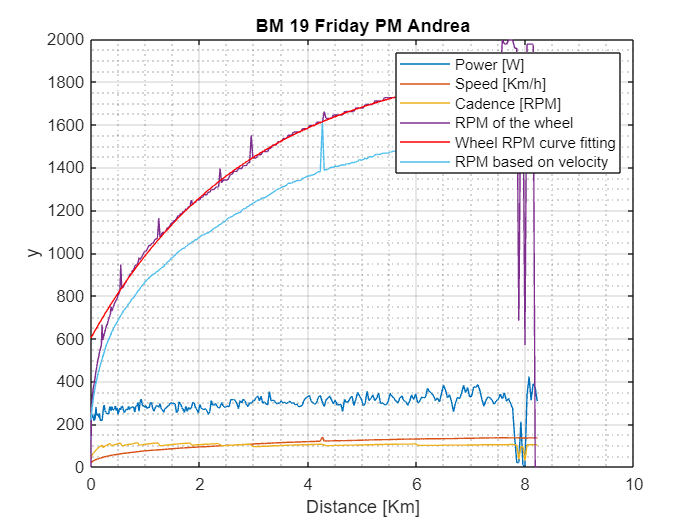

figure 
plot(dist,power,dist,vel,dist,RPM,dist,v);
hold on
plot( fitresult );
hold on 
plot(dist,velocityy);
legend("Power [W]","Speed [Km/h]","Cadence [RPM]","RPM of the wheel","Wheel RPM curve fitting","RPM based on velocity")
title('BM 19 Friday PM Andrea');
xlabel("Distance [Km]");
grid on 
grid minor

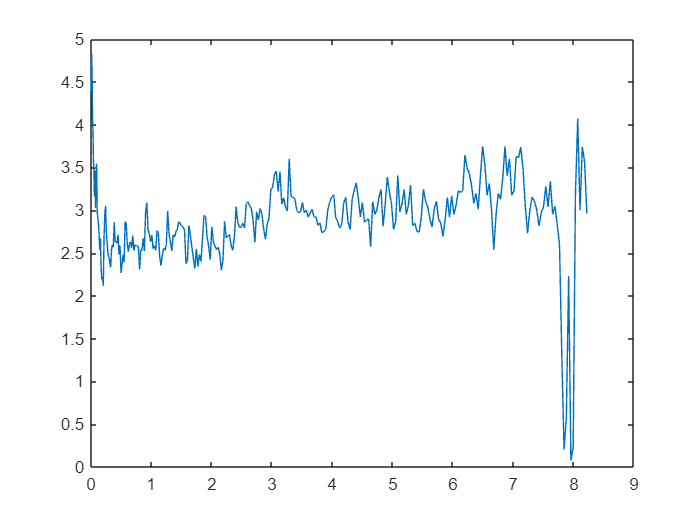

figure
plot(dist, torq);

## Dissipation factor of the gearbox

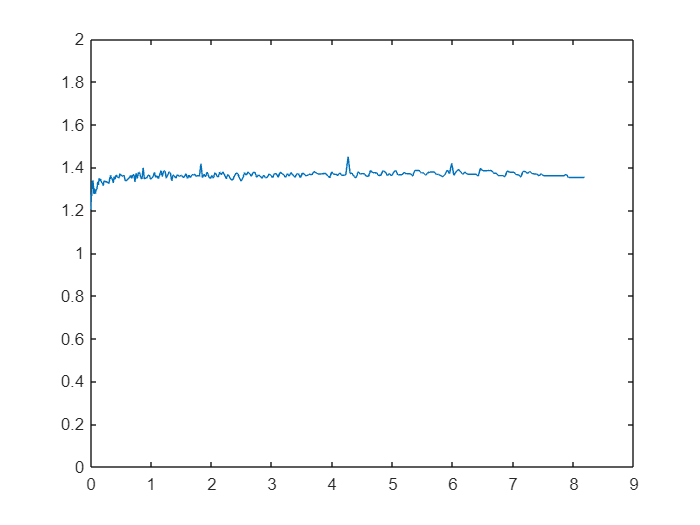

x_data = dist;
a = fitresult.a;
b = fitresult.b;
c = fitresult.c;
d = fitresult.d;
fitted = a*exp(b*x_data) + c*exp(d*x_data);

for i = 1:size(vel,1)-1
    m = 92;
    Jp(i) = 0.5 * m * velocityy(i+1)^2 - velocityy(i)^2;
    Jt(i) = 0.5 * m * v(i+1)^2 - v(i)^2;
    factor(i) = (Jt(i))/Jp(i);
end

for j = 1:size(factor,2)-1

    if abs(factor(j+1)-factor(j)) > 0.1

        factor(j+1) = factor(j);
    else 
        factor(j+1) = factor(j+1);
    end
end 
plot(dist(1:end-1),factor);
ylim([0 2]);

fac_mean = mean(factor)

fac_mean = 1.3601